clc;
clear all;

data = importdata("data.txt");
ground_t = data(:,1);
measurements = data(:,2);

q = 0.001;
r = 1;

% q = 10^-10;
% r = 10^10;

% q = 100;
% r = 10;

dfda = [0 0 0; 0 1 0; 0 0 0];
dgdn = 1;
dgdx = [0 0 1];

Q = [0 0 0; 0 q 0; 0 0 0];
R = [r];

I = eye(3);
S = eye(3);
X = [0; 0; measurements(1)];

for t = 1:1:length(measurements)
    
    X_pred = [X(1)+X(2) ; X(2) ; sin(X(1)*0.1)];
    
%     X_pred = X ;
    
    dfdx = [1 1 0 ; 0 1 0 ; 0.1*(cos(X(1)*0.1)) 0 0];
    
    S_pred = dfdx * S * dfdx' + dfda * Q * dfda';
    
    Y = measurements(t);
    
    K = (S_pred * dgdx') / ((dgdx * S_pred * dgdx') + (dgdn * R * dgdn'));
    
    X = X_pred + K*(Y - X_pred(3));
    
    S = [I-K*dgdx]*S_pred;
    
    estimates(t) = X(3);
end
t = 1:1:length(measurements);

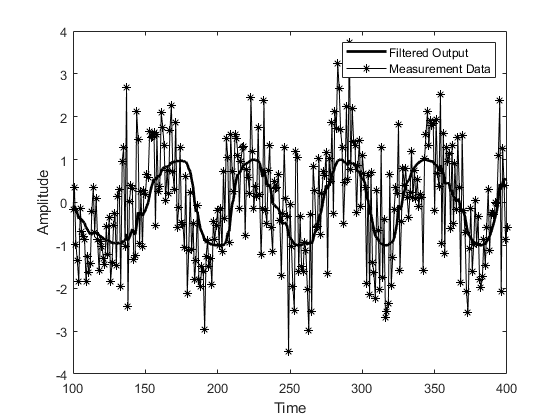


plot(t,estimates,"-k","linewidth",2)
hold on
% plot(t,ground_t,"--k","linewidth",3)
% hold on
plot(t,measurements,"-*k")
xlabel("Time");
ylabel("Amplitude");
% legend("Filtered Output","Ground Truth","Measurement Data");
% legend("Filtered Output","Ground Truth");
legend("Filtered Output","Measurement Data");
% legend("Ground Truth","Measurement Data");
% axis([0 780 -1.5 1.5])
% axis([0 780 -1.5 2])
axis([100 400 -4 4])

% axis([100 500 -2 2])